# 1

A = [1 4 2; 2 4 100; 7 9 7;  3 pi 42];
B = log(A);
a = B(2,:)

a =     0.6931    1.3863    4.6052


b = sum(a)

b = 6.6846

c = B(:,2).*A(:,1)

c =     1.3863
    2.7726
   15.3806
    3.4342


d = max(c)

d = 15.3806

e = sum(A(1,:)./(B(1:3,3))')

e = 3.3391

# 2

clear;clc
v0 = 50;
A = 50;
g = 9.81;

thit = 2*v0*sind(A)/g;
ymax = (v0^2 * sind(A)^2) / (2*g);
fprintf('충돌시간 thit = %.4f s\n', thit);

충돌시간 thit = 7.8088 s


fprintf('최고높이 ymax = %.4f m\n', ymax);

최고높이 ymax = 74.7737 m


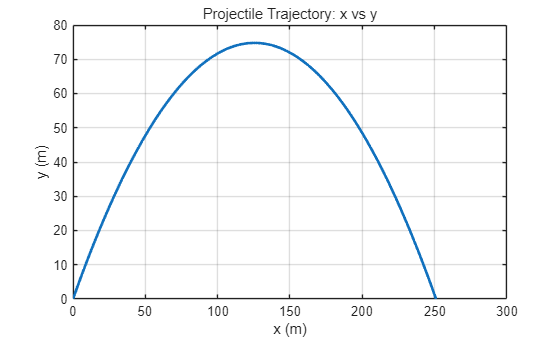

t = linspace(0, thit, 200);
x = (v0*cosd(A)).*t;
y = (v0*sind(A)).*t - 0.5*g*t.^2;
figure;
plot(x, y, 'LineWidth', 2);
grid on;
xlabel('x (m)');
ylabel('y (m)');
title('Projectile Trajectory: x vs y');

# 3

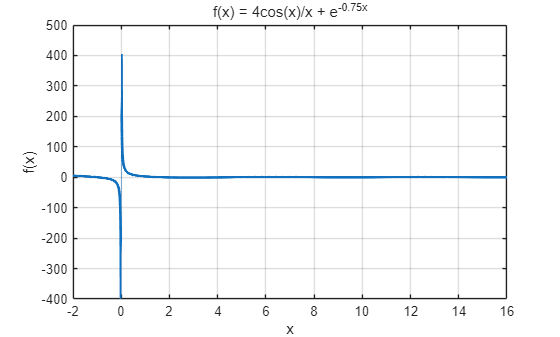

clear;clc
x1 = -2:0.01:-0.01;
x2 = 0.01:0.01:16;
x = [x1 x2];

f = (4*cos(x))./x + exp(-0.75*x);

figure;
plot(x, f, 'LineWidth', 2);
grid on;
xlabel('x');
ylabel('f(x)');
title('f(x) = 4cos(x)/x + e^{-0.75x}');

# 4

clear;clc

p = [300; 550; 400; 250; 500];

Q = [5 4 6;
     3 2 4;
     6 5 3;
     3 5 4;
     2 4 3];

C = p .* Q

monthly_total = sum(C, 1)

material_total = sum(C, 2)

total_all = sum(C, 'all')

# 5

clear;clc

p1 = [5 0 -3 7 10];    
p2 = [4 -7 9 2];        

result = conv(p1, p2)

result =     20   -35    33    59   -36   -13   104    20



num = [5 -7 2 8];
den = [6 3 -2];

[q, r] = deconv(num, den)

q =     0.8333   -1.5833


r =          0         0    8.4167    4.8333



num = [36 -8 0 2];
den = [36 -5 4 -3];

x = 5;

value = polyval(num, x) / polyval(den, x)

value = 0.9795

# 7

% (a)
bridge(1) = struct('location','Smith St.','load',80,'yearBuilt',1928,'yearMaint',2025);
bridge(2) = struct('location','Hope Ave.','load',90,'yearBuilt',1950,'yearMaint',2027);
bridge(3) = struct('location','Clark St.','load',85,'yearBuilt',1933,'yearMaint',2024);
bridge(4) = struct('location','North Rd.','load',100,'yearBuilt',1960,'yearMaint',2023);

% (b)
bridge(3).yearMaint = 2026;

% (c)
bridge(5) = struct('location','Shore Rd.','load',85,'yearBuilt',1997,'yearMaint',2022);